%6.2.1   第一部分简单合成音乐
%问题1


tone=[5,5,6,2,1,1,6,2]

tone =      5     5     6     2     1     1     6     2


f=cal_f(tone,523.25)

f =   783.9892  783.9892  879.9981  587.3283  523.2500  523.2500  879.9981  587.3283


f(7)=f(7)/2;
f=f*1;%完成频率计算

fs=8000; %采样频率
T = 4;  %设置音乐总时长为4s
t = linspace(0,T*1,T*fs);       %创建时间序列
song = 0 * t;%歌曲序列
one_step = 0.5;      %一个节拍所需时间 

last_time=[1,0.5,0.5,2,1,0.5,0.5,2];
left_t=0 %定义当前时间

left_t = 0

nums=length(tone)

nums = 8

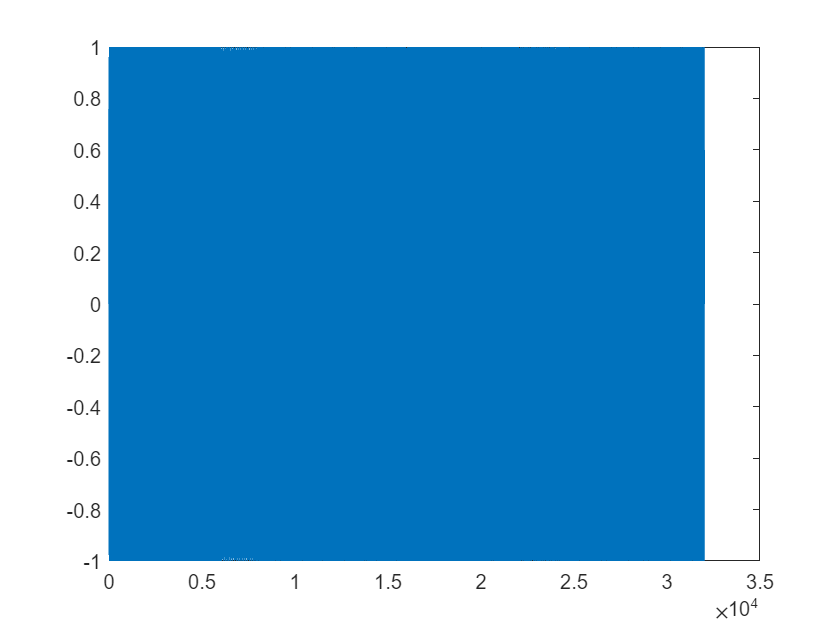

for i=1:nums
    gate=(t>=left_t&t<left_t+one_step*last_time(i));
    song=song+gate.*sin(2*pi*f(i)*(t-left_t));
    left_t=left_t+one_step*last_time(i);

    %  gate = (t >= left_t) & (t < left_t + one_step*last_time(i));
    % song = song + gate.*sin(2*pi*f(i)*(t - left_t)); % 修正 sin 函数的参数
    % left_t = left_t + one_step*last_time(i); % 修正 left_t 的更新
end

sound(song,fs)
plot(song)

%问题2


% 延长单个音符时间以使得音符间存在重叠
tone=[5,5,6,2,1,1,6,2]

tone =      5     5     6     2     1     1     6     2


f=cal_f(tone,523.25)

f =   783.9892  783.9892  879.9981  587.3283  523.2500  523.2500  879.9981  587.3283


f(7)=f(7)/2;
f=f*1;%完成频率计算

fs=8000; %采样频率
T = 4;  %设置音乐总时长为4s
t = linspace(0,T*1,T*fs);       %创建时间序列
song = 0 * t;%歌曲序列
one_step = 0.5;      %一个节拍所需时间 

last_time=[1,0.5,0.5,2,1,0.5,0.5,2];
left_t=0 %定义当前时间

left_t = 0

scale=1.1

scale = 1.1000

nums=length(tone)

nums = 8

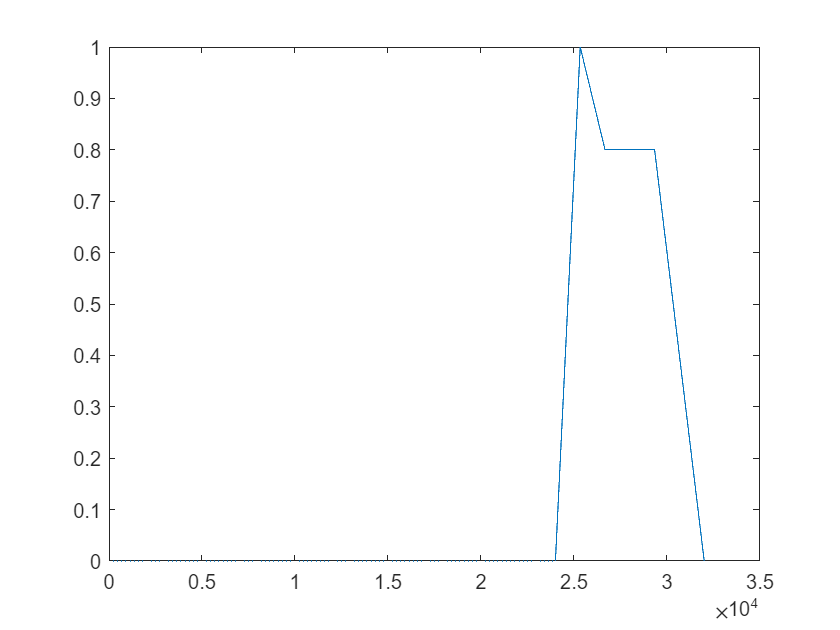

for i=1:nums
    gate=(t>=left_t&t<left_t+one_step*last_time(i)*scale);
   song_of_single_key=gate.*sin(2*pi*f(i)*(t-left_t));
    sosk_adj=adj_music(song_of_single_key,left_t,one_step*last_time(i)*scale,t);
    song=sosk_adj+song;
    left_t=left_t+one_step*last_time(i);
end

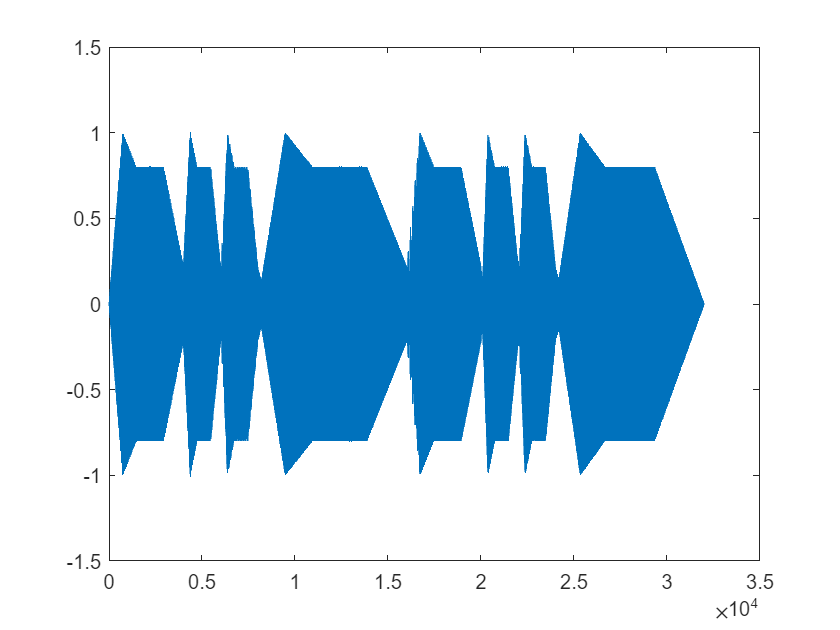


sound(song,fs)
plot(song)

%问题3

% 升调 降调
tone=[5,5,6,2,1,1,6,2]

tone =      5     5     6     2     1     1     6     2


f=cal_f(tone,523.25)

f =   783.9892  783.9892  879.9981  587.3283  523.2500  523.2500  879.9981  587.3283


f(7)=f(7)/2;
f=f*1;%完成频率计算

fs=4000; %采样频率
T = 4;  %设置音乐总时长为4s
t = linspace(0,T*1,T*fs);       %创建时间序列
song = 0 * t;%歌曲序列
one_step = 0.5;      %一个节拍所需时间 

last_time=[1,0.5,0.5,2,1,0.5,0.5,2];
left_t=0 %定义当前时间

left_t = 0

scale=1.1

scale = 1.1000

nums=length(tone)

nums = 8

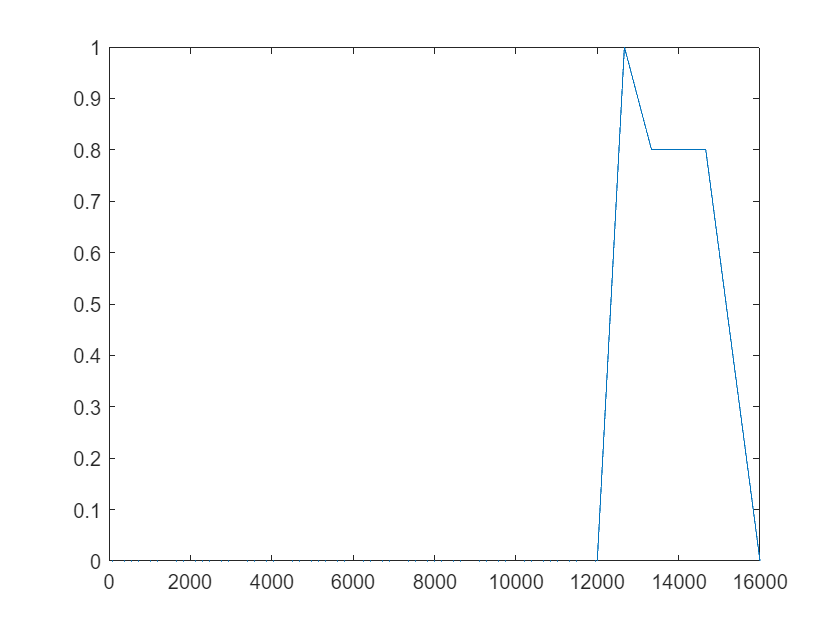

for i=1:nums
    gate=(t>=left_t&t<left_t+one_step*last_time(i)*scale);
   song_of_single_key=gate.*sin(2*pi*f(i)*(t-left_t));
    sosk_adj=adj_music(song_of_single_key,left_t,one_step*last_time(i)*scale,t);
    song=sosk_adj+song;
    left_t=left_t+one_step*last_time(i);
end

fs=fs*2

fs = 8000

% sound(song,fs)
% plot(song)

fs1=fs*1.05;

sound(song,fs1)

%问题4

tone=[5,5,6,2,1,1,6,2]

tone =      5     5     6     2     1     1     6     2


f=cal_f(tone,523.25)

f =   783.9892  783.9892  879.9981  587.3283  523.2500  523.2500  879.9981  587.3283


f(7)=f(7)/2;
f=f*1;%完成频率计算

fs=4000; %采样频率
T = 4;  %设置音乐总时长为4s
t = linspace(0,T*1,T*fs);       %创建时间序列
song = 0 * t;%歌曲序列
one_step = 0.5;      %一个节拍所需时间 

last_time=[1,0.5,0.5,2,1,0.5,0.5,2];
left_t=0 %定义当前时间

left_t = 0

scale=1.1

scale = 1.1000

weight = [1,0.21,0.2];    %各谐波分量权重
nums=length(tone)

nums = 8

for i=1:nums
    gate=(t>=left_t&t<left_t+one_step*last_time(i)*scale);
   song_of_single_key= gate.* ( (weight(1)+0.005*rand(1))*sin( 2*pi*f(i)*(t-left_t)) + (weight(2)+0.005*rand(1))*sin( 4*pi*f(i)*(t-left_t)) +  (weight(3)+0.005*rand(1))*sin( 6*pi*f(i)*(t-left_t))); 
    sosk_adj=adj_music(song_of_single_key,left_t,one_step*last_time(i)*scale,t);
    song=sosk_adj+song;
    left_t=left_t+one_step*last_time(i);
end

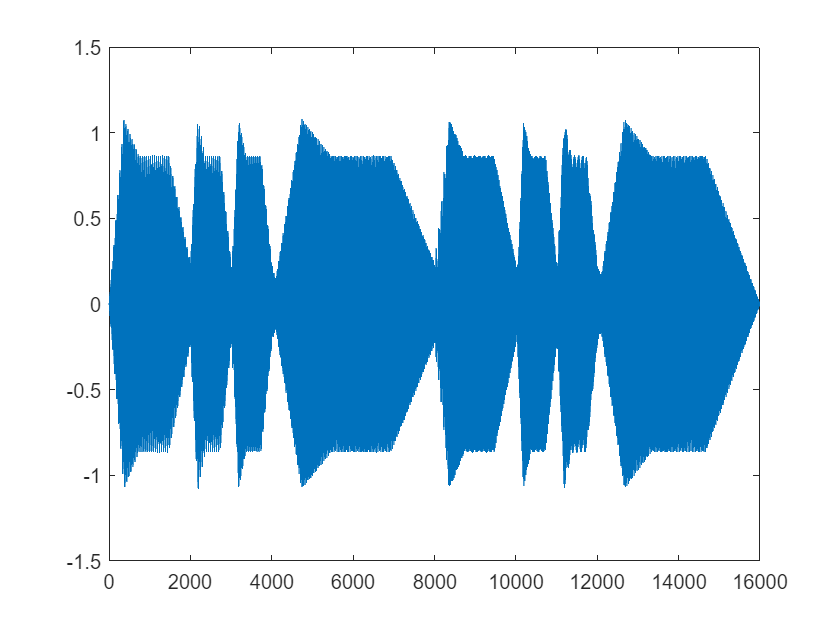

sound(song,fs)
plot(song)

%问题5   演奏小星星

% 小星星 1=C 演奏
tone=[1,1,5,5,6,6,5,4,4,3,3,2,2,1,5,5,4,4,3,3,2,5,5,4,4,3,3,2,1,1,5,5,6,6,5,4,4,3,3,2,2,1]

tone =      1     1     5     5     6     6     5     4     4     3     3     2     2     1     5     5     4     4     3     3     2     5     5     4     4     3     3     2     1     1     5     5     6     6     5     4     4     3     3     2     2     1


f=cal_f(tone,261.63)

f =   261.6300  261.6300  392.0021  392.0021  440.0075  440.0075  392.0021  349.2342  349.2342  329.6331  329.6331  293.6697  293.6697  261.6300  392.0021  392.0021  349.2342  349.2342  329.6331  329.6331  293.6697  392.0021  392.0021  349.2342  349.2342  329.6331  329.6331  293.6697  261.6300  261.6300  392.0021  392.0021  440.0075  440.0075  392.0021  349.2342  349.2342  329.6331  329.6331  293.6697  293.6697  261.6300


f=f*1;%完成频率计算

fs=4000; %采样频率
T = 24;  %设置音乐总时长为24s
t = linspace(0,T*1,T*fs);       %创建时间序列
song = 0 * t;%歌曲序列
one_step = 0.5;      %一个节拍所需时间 

last_time=[1,1,1,1,1,1,2,1,1,1,1,1,1,2,1,1,1,1,1,1,2,1,1,1,1,1,1,2,1,1,1,1,1,1,2,1,1,1,1,1,1,2];
left_t=0 %定义当前时间

left_t = 0

scale=1.1

scale = 1.1000

weight = [1,0.21,0.2];    %各谐波分量权重
nums=length(tone)

nums = 42

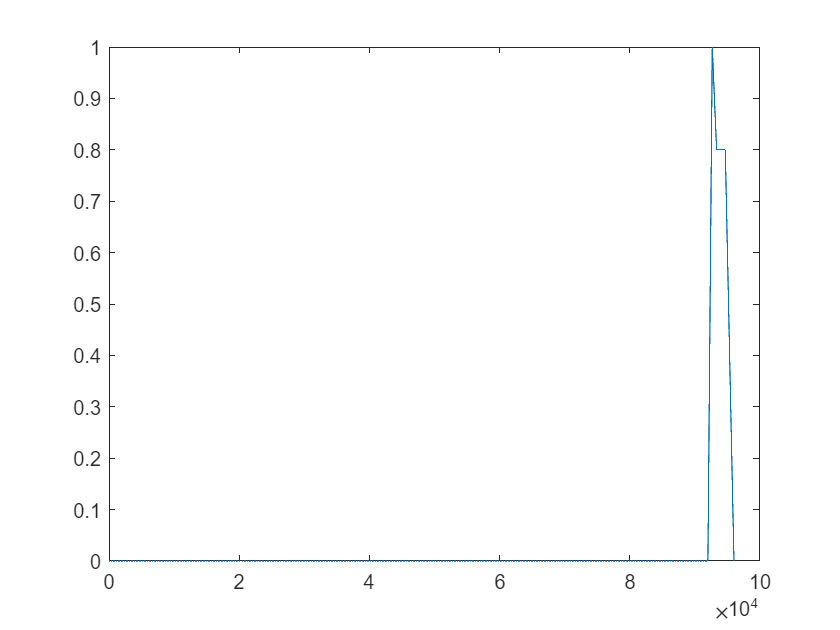

for i=1:nums
    gate=(t>=left_t&t<left_t+one_step*last_time(i)*scale);
   song_of_single_key= gate.* ( (weight(1)+0.005*rand(1))*sin( 2*pi*f(i)*(t-left_t)) + (weight(2)+0.005*rand(1))*sin( 4*pi*f(i)*(t-left_t)) +  (weight(3)+0.005*rand(1))*sin( 6*pi*f(i)*(t-left_t))); 
    sosk_adj=adj_music(song_of_single_key,left_t,one_step*last_time(i)*scale,t);
    song=sosk_adj+song;
    left_t=left_t+one_step*last_time(i);
end

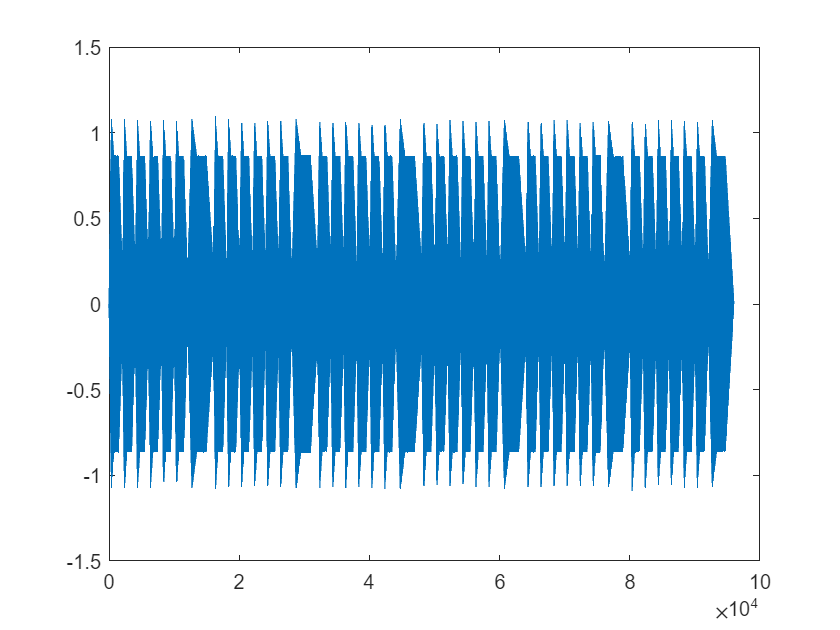

sound(song,fs)
plot(song)